# Motion perception

### 1. Construct psychometric curve

#### (1) Defined the psychometric curve using Weibull function

clear all; clc;
load MTdata.mat

p_c = @(b, x) 1-0.5*exp(-(max(x, eps)/b(1)).^b(2)); % b(1)=α, b(2)=β

#### (2) Calculate the choice accuracy in each coherence and fit the data with defined curve

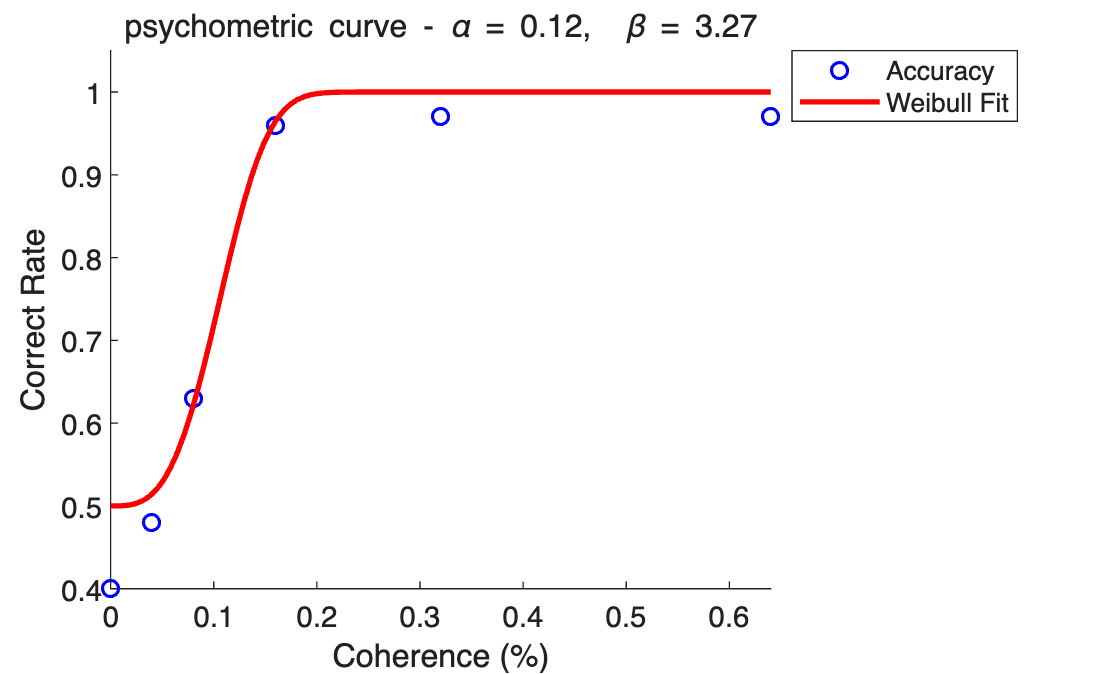

for i = 1:size(MTdata, 3)
    label = MTdata(:,3,i);
    num_correct(i) = sum(label == 1);
    accuracy(i) = num_correct(i)/size(MTdata,1);
end
init_params = [0.1 1];
params = nlinfit(coherence, accuracy, p_c, init_params);
alpha = params(1);
beta = params(2);
figure;
x = linspace(min(coherence), max(coherence), 100);
y = p_c(params, x);
hold on;
plot(coherence, accuracy, 'bo', 'LineWidth', 1.2);
plot(x, y, 'r-', 'LineWidth', 2);
xlabel('Coherence (%)');
ylabel('Correct Rate');
legend('Accuracy', 'Weibull Fit', 'Location','northeastoutside');
title(['psychometric curve - ', '\alpha = ', num2str(alpha, '%.2f'), ',  \beta = ', num2str(beta, '%.2f')]);
ylim([0.4 1.05]);
hold off;

### 2. Construct a neurometric curve

#### (1) ROC curve and AUC value

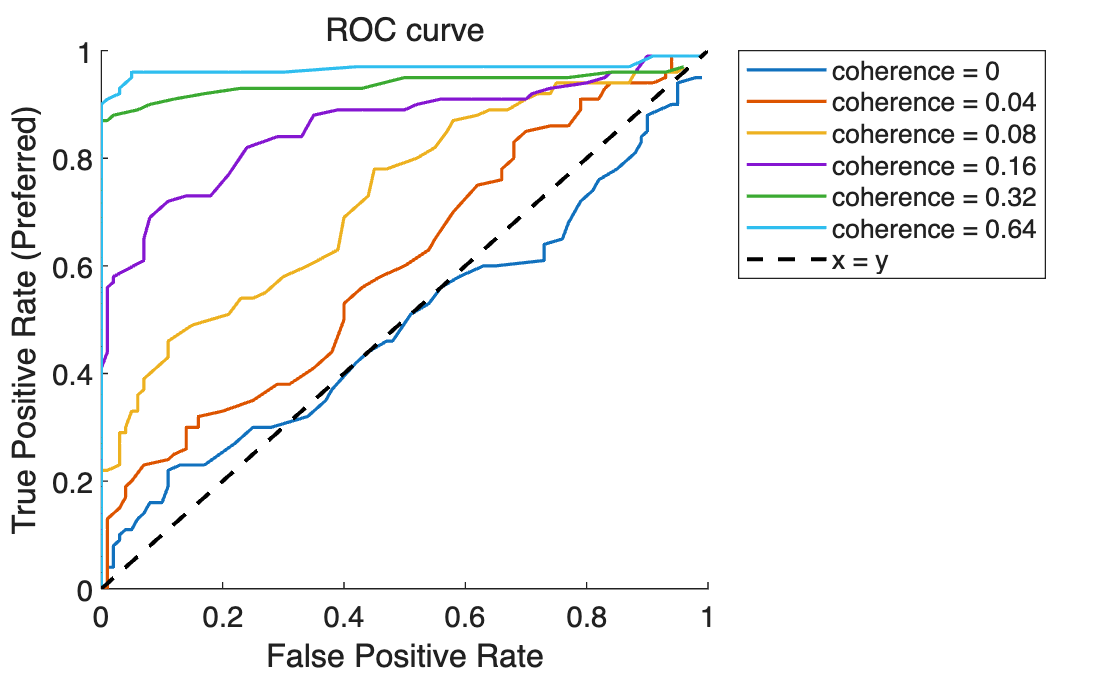

cmap = lines(size(MTdata,3));
figure;
hold on;
for i = 1:size(MTdata,3)
    data = MTdata(:,:,i);
    null = data(:,1);
    prefered = data(:,2);
    for criterion = 1:100
        ratio_null(criterion) = sum(null>criterion)/length(null);
        ratio_prefered(criterion) = sum(prefered>criterion)/length(prefered);
    end
    AUC(i) = trapz(ratio_null, ratio_prefered);

    plot(ratio_null, ratio_prefered, 'Color', cmap(i,:), 'LineWidth', 1.2, 'DisplayName', ['coherence = ', num2str(coherence(i))]);
end
plot([0 1], [0 1], 'k--', 'LineWidth', 1.5, 'DisplayName', 'x = y');
title('ROC curve');
xlabel('False Positive Rate');
ylabel('True Positive Rate (Preferred)');
legend('Location','northeastoutside');
hold off;

#### (2) Using AUC and coherence data to fit with defined p_c curve  

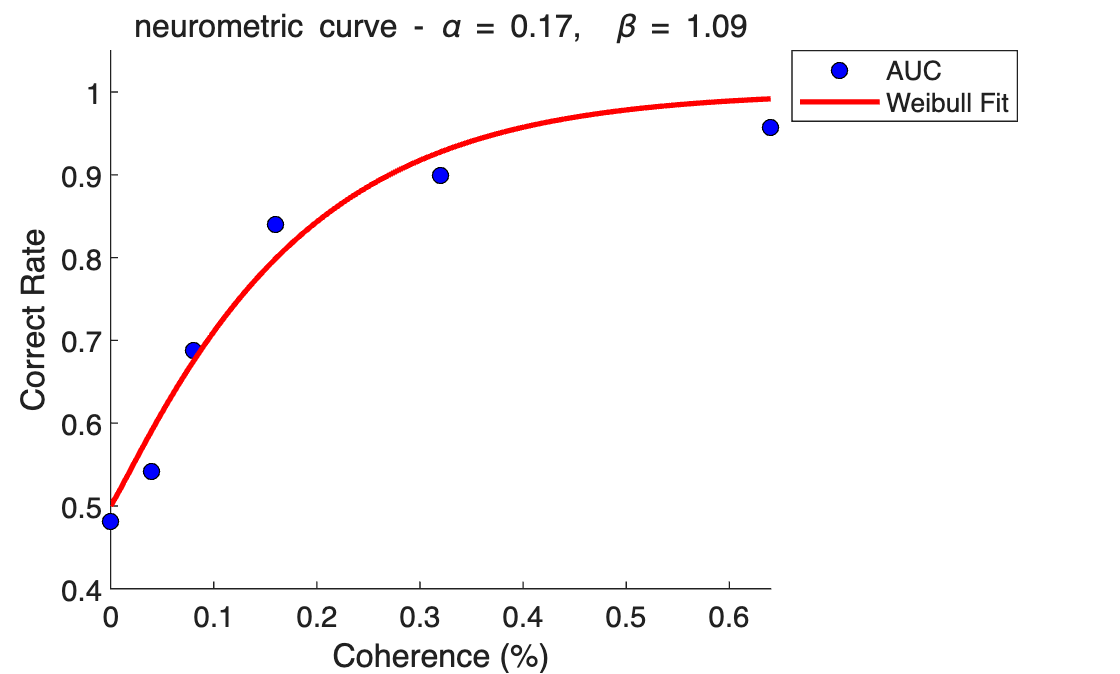

AUC = -AUC;
init_params = [0.1 1];
params = nlinfit(coherence, AUC, p_c, init_params);
alpha = params(1);
beta = params(2);
figure;
x = linspace(min(coherence), max(coherence), 100);
y = p_c(params, x);
hold on;
plot(coherence, AUC, 'ko', 'MarkerFaceColor', 'b');
plot(x, y, 'r-', 'LineWidth', 2);
xlabel('Coherence (%)');
ylabel('Correct Rate');
legend('AUC', 'Weibull Fit', 'Location','northeastoutside');
title(['neurometric curve - ', '\alpha = ', num2str(alpha, '%.2f'), ',  \beta = ', num2str(beta, '%.2f')]);
ylim([0.4 1.05]);
hold off;

#### (3) plot them together

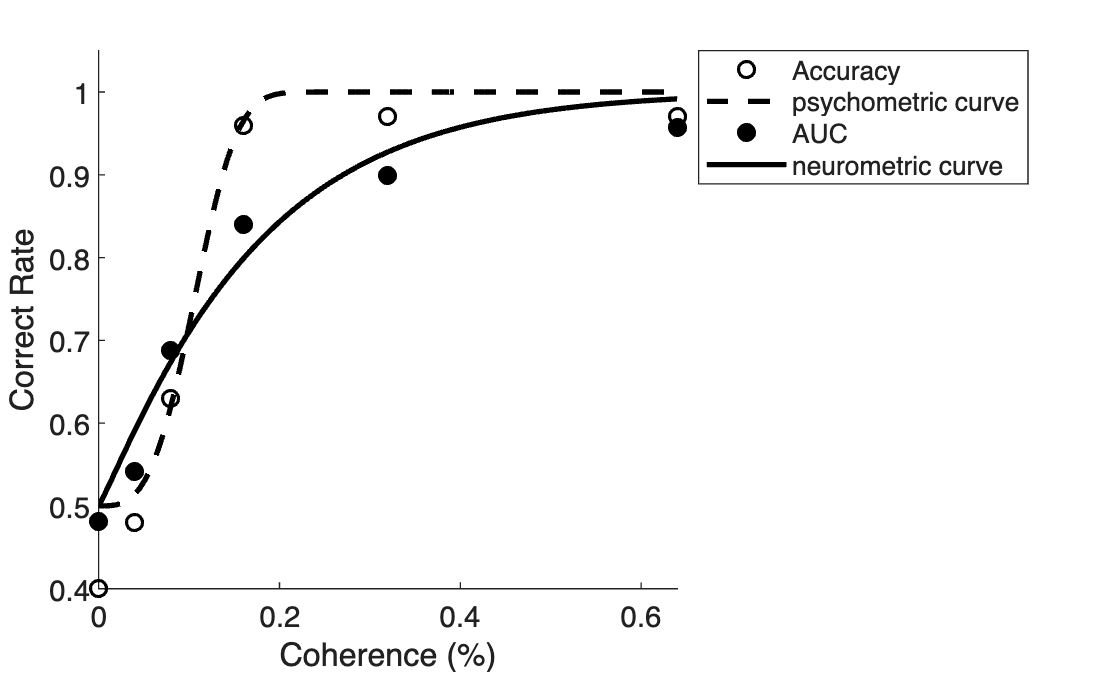

init_params = [0.1 1];
params_p = nlinfit(coherence, accuracy, p_c, init_params);
alpha_p = params_p(1);
beta_p = params_p(2);
x_p = linspace(min(coherence), max(coherence), 100);
y_p = p_c(params_p, x_p);

params_n = nlinfit(coherence, AUC, p_c, init_params);
alpha_n = params_n(1);
beta_n = params_n(2);
x_n = linspace(min(coherence), max(coherence), 100);
y_n = p_c(params_n, x_n);

figure;
hold on;
plot(coherence, accuracy, 'ko', 'LineWidth', 1.2, 'DisplayName', 'Accuracy');
plot(x_p, y_p, 'k--', 'LineWidth', 2, 'DisplayName', 'psychometric curve');

plot(coherence, AUC, 'ko', 'LineWidth', 1.2, 'MarkerFaceColor', 'k', 'DisplayName', 'AUC');
plot(x_n, y_n, 'k-', 'LineWidth', 2, 'DisplayName', 'neurometric curve');
xlabel('Coherence (%)');
ylabel('Correct Rate');
legend('Location','northeastoutside');
ylim([0.4 1.05]);
hold off;

### 4. Calculate the “choice probability”.

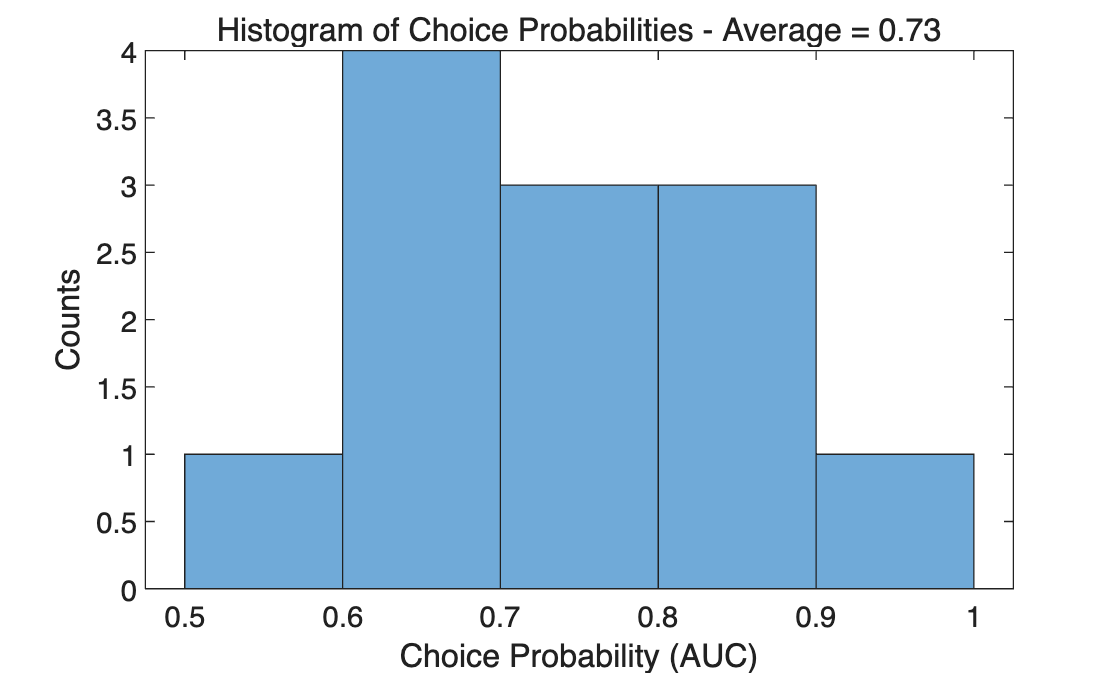

for i = 1:size(MTdata,3)
    leftward_cell_data = MTdata(:,1,i);
    rightward_cell_data = MTdata(:,2,i);

    leftward_cell_leftchoice = leftward_cell_data(MTdata(:,3,i) == 0);
    leftward_cell_rightchoice = leftward_cell_data(MTdata(:,3,i) == 1);

    rightward_cell_leftchoice = rightward_cell_data(MTdata(:,3,i) == 0);
    rightward_cell_rightchoice = rightward_cell_data(MTdata(:,3,i) == 1);

    for j = 1:100
        ratio_left_null(j) = sum(leftward_cell_rightchoice>j)/length(leftward_cell_rightchoice);
        ratio_left_prefered(j) = sum(leftward_cell_leftchoice>j)/length(leftward_cell_leftchoice);
        ratio_right_null(j) = sum(rightward_cell_leftchoice>j)/length(rightward_cell_leftchoice);
        ratio_right_prefered(j) = sum(rightward_cell_rightchoice>j)/length(rightward_cell_rightchoice);
    end
    AUC_left(i) = trapz(ratio_left_null, ratio_left_prefered);
    AUC_right(i) = trapz(ratio_right_null, ratio_right_prefered);
end
AUC_left = -AUC_left;
AUC_right = -AUC_right;

choice_probability = mean([AUC_left, AUC_right]);

figure;
histogram([AUC_left,AUC_right],'BinLimits',[0.5 1], 'NumBins', 5);
xlabel('Choice Probability (AUC)');
ylabel('Counts');
title(['Histogram of Choice Probabilities - ', 'Average = ', num2str(choice_probability, '%.2f')]);